# Offline RL for GBWM — Week 4: Real Data Baseline

Same as Week 3 (shaped reward + more episodes + multi-window eval), only the data layer is swapped: - data/SimulatedData.xlsx (3 simulated assets) -> data/prices_train.csv & data/prices_test.csv (15 real assets, 2010-2025) - price2ret -> diff(log(P)) (R2025b moved price2ret to Econometrics Toolbox) - {:, 3:end} -> {:, 2:end} (new CSV has 1 Date column, not 2) Everything else (reward shaping, agent, training, eval) is unchanged.

clear; clc;

%multi random seed tests
rng(1000, "twister");

## Parameter Settings

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 2000;
horizonPeriods  = 30;
numEpisodes     = 130;
numActions      = 15;

logsFolder      = fullfile("experiments", "logs", "week4_realdata");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

## Load data and build action set

pricesTT   = readtable("data/prices_train.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);   % skip Date column
P_train    = pricesTT{:, 2:end};                          % numeric matrix
R_train    = diff(log(P_train));                          % continuous returns

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

pricesTT

pricesTT = 2516×16 table
       Date        AAPL      MSFT      NVDA       JPM       BAC        V        JNJ       UNH       XOM       CVX        PG        KO       CAT       TLT       GLD  
    __________    ______    ______    _______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    2010-01-04    6.4065    23.028    0.42329    28.279    12.038    19.565    39.975    24.408   

W_frontier

W_frontier =     0.0271    0.0406    0.0569    0.0742    0.0932    0.1109    0.1284    0.1430    0.1545    0.1661    0.1777    0.1893    0.0452         0         0
    0.0030    0.0025    0.0003         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0078    0.0175    0.0277    0.0407    0.0566    0.0727    0.0902    0.1090    0.1279    0.1467    0.1655    0.3100    0.6389    1.0000
    0.0306    0.0435    0.0378    0.0238    0.0070         0         0         0         0         0         0         0         0         0         0
    0.0256    0.0058         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0209    0.0343    0.0491    0.0646    0.0837    0.0997    0.1146    0.1187    0.1119    0.1051    0.0983    0.0914         0         0         0
    0.1466    0.1598    0.1707    0.1801    0.1831    0.1179    0.0397         0 

## Build offline episodes — SHAPED REWARD

if ~isfolder(logsFolder); mkdir(logsFolder); end

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

episodeCount = 0;
startIdx     = 1;
stepSize     = floor(horizonPeriods/2);

while episodeCount < numEpisodes && (startIdx + horizonPeriods - 1) <= size(R_sub,1)
    episodeCount = episodeCount + 1;
    expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
        "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

    wealth = initialWealth;
    for t = 1:horizonPeriods
        obs  = [normalizeWealth(wealth); timeFrac(t)];
        aIdx = randi(numActions);
        w    = W_frontier(:, aIdx);

        r_tp1      = R_sub(startIdx + t - 1, :) * w;
        wealthNext = (wealth + contribution) * (1 + r_tp1);

        % dense per-step log return + terminal bonus
        reward = log(wealthNext / wealth);
        if t == horizonPeriods && wealthNext >= goalWealth
            reward = reward + 1.0;
        end

        nextObs = [normalizeWealth(wealthNext); timeFrac(min(t+1, horizonPeriods))];
        isDone  = (t == horizonPeriods);

        expStruct(t).Observation     = {obs};
        expStruct(t).Action          = {aIdx};
        expStruct(t).Reward          = reward;
        expStruct(t).NextObservation = {nextObs};
        expStruct(t).IsDone          = isDone;

        wealth = wealthNext;
    end

    epFile = fullfile(logsFolder, sprintf("loggedData%03d.mat", episodeCount));
    exp = expStruct;
    save(epFile, "exp");
    startIdx = startIdx + stepSize;
end

fprintf("Saved %d episodes (%d steps each), %d total transitions.\n", ...
    episodeCount, horizonPeriods, episodeCount * horizonPeriods);

Saved 130 episodes (30 steps each), 3900 total transitions.


## FileDatastore

myReadFcn = @(fname) load(fname, "exp").exp;
fds = fileDatastore(logsFolder, "ReadFcn", myReadFcn, "FileExtensions", ".mat");

## Build DQN agent

obsInfo = rlNumericSpec([2 1], Name="GBWMObservation");
actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

criticLG = layerGraph([
    featureInputLayer(obsInfo.Dimension(1), Name="state")
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(numActions, Name="Qout")
    ]);

criticNet = dlnetwork(criticLG);
critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

agentOpts = rlDQNAgentOptions( ...
    DiscountFactor=discountFactor, ...
    ExperienceBufferLength=1e6, ...
    MiniBatchSize=miniBatchSize, ...
    TargetUpdateMethod="periodic", ...
    TargetUpdateFrequency=4, ...
    UseDoubleDQN=true);
agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
agent = rlDQNAgent(critic, agentOpts);

## Train offline

tfdOpts = rlTrainingFromDataOptions( ...
    MaxEpochs        = maxEpochs, ...
    NumStepsPerEpoch = stepsPerEpoch, ...
    Plots            = "training-progress", ...
    Verbose          = true);
tfdStats = trainFromData(agent, fds, tfdOpts);

Epoch:    1/ 100 | Step Count:    400/40000 | Q Value:   0.6858 | Num experiences added: 3900
Epoch:    2/ 100 | Step Count:    800/40000 | Q Value:   0.5277 | Num experiences added:    0
Epoch:    3/ 100 | Step Count:   1200/40000 | Q Value:   0.3841 | Num experiences added:    0
Epoch:    4/ 100 | Step Count:   1600/40000 | Q Value:   0.3763 | Num experiences added:    0
Epoch:    5/ 100 | Step Count:   2000/40000 | Q Value:   0.3729 | Num experiences added:    0
Epoch:    6/ 100 | Step Count:   2400/40000 | Q Value:   0.3544 | Num experiences added:    0
Epoch:    7/ 100 | Step Count:   2800/40000 | Q Value:   0.3339 | Num experiences added:    0
Epoch:    8/ 100 | Step Count:   3200/40000 | Q Value:   0.3334 | Num experiences added:    0
Epoch:    9/ 100 | Step Count:   3600/40000 | Q Value:   0.3322 | Num experiences added:    0
Epoch:   10/ 100 | Step Count:   4000/40000 | Q Value:   0.3192 | Num experiences added:    0
Epoch:   11/ 100 | Step Count:   4400/40000 | Q Value:   0.3

save(fullfile(logsFolder, "TrainedAgent.mat"), "agent");

## Multi-window hold-out evaluation

R_full = inputTestData('data/prices_test.csv');

numEvalEpisodes = 30;
successCount    = 0;
allSharpes      = nan(numEvalEpisodes, 1);
allMaxDD        = nan(numEvalEpisodes, 1);
allTermWealth   = nan(numEvalEpisodes, 1);
allWealthPaths  = cell(numEvalEpisodes, 1);

fprintf("\n=== Multi-window hold-out evaluation ===\n");


=== Multi-window hold-out evaluation ===


for ep = 1:numEvalEpisodes
    startEval = (ep-1)*horizonPeriods + 1;
    if startEval + horizonPeriods - 1 > size(R_full, 1)
        fprintf("Ep %d: skipped (insufficient data)\n", ep);
        break;
    end

    wealth = zeros(horizonPeriods+1, 1);
    wealth(1) = initialWealth;
    chosenActions = zeros(1, horizonPeriods);
    for t = 1:horizonPeriods
        obs     = { [normalizeWealth(wealth(t)); timeFrac(t)] };
        aGreedy = agent.getAction(obs);
        chosenActions(t) = aGreedy{1};
        w       = W_frontier(:, aGreedy{1});
        r_tp1   = R_full(startEval + t - 1, :) * w;
        wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
    end

    rets    = diff(log(wealth));
    sharpe  = mean(rets) / std(rets) * sqrt(252);
    maxDD   = max(cummax(wealth) - wealth) / max(wealth);
    success = (wealth(end) >= goalWealth);

    allSharpes(ep)     = sharpe;
    allMaxDD(ep)       = maxDD;
    allTermWealth(ep)  = wealth(end);
    allWealthPaths{ep} = wealth;
    successCount       = successCount + double(success);

    fprintf("Ep %d: terminal=%.0f, success=%d, Sharpe=%.2f, MaxDD=%.2f%%\n", ...
        ep, wealth(end), success, sharpe, maxDD*100);
    fprintf("  actions: %s\n", mat2str(chosenActions));
end

Ep 1: terminal=93007, success=0, Sharpe=-1.51, MaxDD=17.49%


  actions: [15 15 12 12 12 12 12 12 12 12 12 12 13 13 13 13 13 13 13 13 13 13 14 14 14 14 14 14 14 14]


Ep 2: terminal=104382, success=1, Sharpe=0.89, MaxDD=11.45%


  actions: [15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 13 13 12 7 7 14 7 14 14 14]


Ep 3: terminal=75145, success=0, Sharpe=-5.51, MaxDD=24.85%


  actions: [15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 13 13 14 14 14 14 14 14 14 14 14]


Ep 4: terminal=99938, success=0, Sharpe=-0.01, MaxDD=17.91%


  actions: [15 15 15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 14 14 14 14 14 14]


Ep 5: terminal=94553, success=0, Sharpe=-1.53, MaxDD=9.15%


  actions: [15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 7 7 7 14 14 14 14]


Ep 6: terminal=90004, success=0, Sharpe=-2.24, MaxDD=19.67%


  actions: [15 15 15 15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 13 13 13 13 13 13 14 14 14 14 14 14]


Ep 7: terminal=100564, success=0, Sharpe=0.15, MaxDD=9.92%


  actions: [15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 13 12 12 13 13 13 7 7 7 14 14 14 14]


Ep 8: terminal=124605, success=1, Sharpe=3.10, MaxDD=7.82%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14 14 14 14 14 14 14 14]


Ep 9: terminal=98974, success=0, Sharpe=-0.33, MaxDD=10.80%


  actions: [15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 13 13 13 14 14 14 14 14]


Ep 10: terminal=109527, success=1, Sharpe=1.82, MaxDD=10.97%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 12 12 12 12 12 12 12 12 7 7 7 7 7 14 14 14]


Ep 11: terminal=110043, success=1, Sharpe=3.24, MaxDD=6.54%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 12 12 12 12 12 12 14 14 14 14 14 14 14 14]


Ep 12: terminal=105680, success=1, Sharpe=1.62, MaxDD=6.37%


  actions: [15 15 15 15 15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 14 7 14 14 14 14 14 14]


Ep 13: terminal=105606, success=1, Sharpe=1.65, MaxDD=8.40%


  actions: [15 15 15 15 15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 7 7 7 14 14 14 14 14]


Ep 14: terminal=94399, success=0, Sharpe=-2.12, MaxDD=8.67%


  actions: [15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 13 14 14 14 14 14 14]


Ep 15: terminal=94522, success=0, Sharpe=-2.52, MaxDD=6.74%


  actions: [15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 7 7 7 14 14 14 14]


Ep 16: terminal=104355, success=1, Sharpe=1.70, MaxDD=5.90%


  actions: [15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 7 7 7 7 7 14 14 14]


Ep 17: terminal=102347, success=1, Sharpe=1.04, MaxDD=4.83%


  actions: [15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 14 14 14 14 14]


Ep 18: terminal=130829, success=1, Sharpe=5.41, MaxDD=6.01%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14 14 14 14 14 14 14]


Ep 19: terminal=110821, success=1, Sharpe=2.06, MaxDD=10.77%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14 14 14 14 14 14 14 14 14]


Ep 20: terminal=109112, success=1, Sharpe=2.71, MaxDD=5.89%


  actions: [15 15 12 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 7 7 7 14 14 14 14]


Ep 21: terminal=116578, success=1, Sharpe=2.84, MaxDD=13.63%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 12 14 14 14 14 14 14 14 14 14]


Ep 22: terminal=101952, success=0, Sharpe=0.39, MaxDD=14.12%


  actions: [15 15 15 15 12 15 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 13 14 14 14 14 14 14 14]


Ep 23: terminal=96182, success=0, Sharpe=-1.37, MaxDD=6.68%


  actions: [15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 7 14 14 14 14 14]


Ep 24: terminal=123277, success=1, Sharpe=5.20, MaxDD=5.77%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14 14 14 14 14 14 14 14 14]


Ep 25: terminal=89277, success=0, Sharpe=-3.55, MaxDD=15.24%


  actions: [15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 13 13 13 14 14 14 14 14 14 14 14]


Ep 26: terminal=101026, success=0, Sharpe=0.24, MaxDD=11.00%


  actions: [15 15 15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 7 7 7 14 14 14 14]


Ep 27: terminal=96388, success=0, Sharpe=-1.07, MaxDD=10.09%


  actions: [15 15 15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 12 7 7 7 14 14 14 14]


Ep 28: terminal=78432, success=0, Sharpe=-3.26, MaxDD=24.05%


  actions: [15 15 15 15 15 12 12 12 12 12 12 12 12 12 12 13 13 13 13 13 14 14 14 14 14 14 14 14 14 14]


Ep 29: terminal=125292, success=1, Sharpe=5.87, MaxDD=2.95%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14 14 14 14 14 14 14 14]


Ep 30: terminal=110846, success=1, Sharpe=2.78, MaxDD=7.96%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 12 14 14 14 14 14 14 14 14 14 14]


fprintf("\n--- Summary ---\n");


--- Summary ---


fprintf("Success rate : %d / %d\n", successCount, numEvalEpisodes);

Success rate : 15 / 30


fprintf("Mean Sharpe  : %.2f (std %.2f)\n", ...
    mean(allSharpes,'omitnan'), std(allSharpes,'omitnan'));

Mean Sharpe  : 0.59 (std 2.75)


fprintf("Mean MaxDD   : %.2f%% (std %.2f%%)\n", ...
    mean(allMaxDD,'omitnan')*100, std(allMaxDD,'omitnan')*100);

Mean MaxDD   : 10.72% (std 5.52%)


fprintf("Mean Terminal Wealth: %.0f\n", mean(allTermWealth,'omitnan'));

Mean Terminal Wealth: 103255


## Plot wealth paths

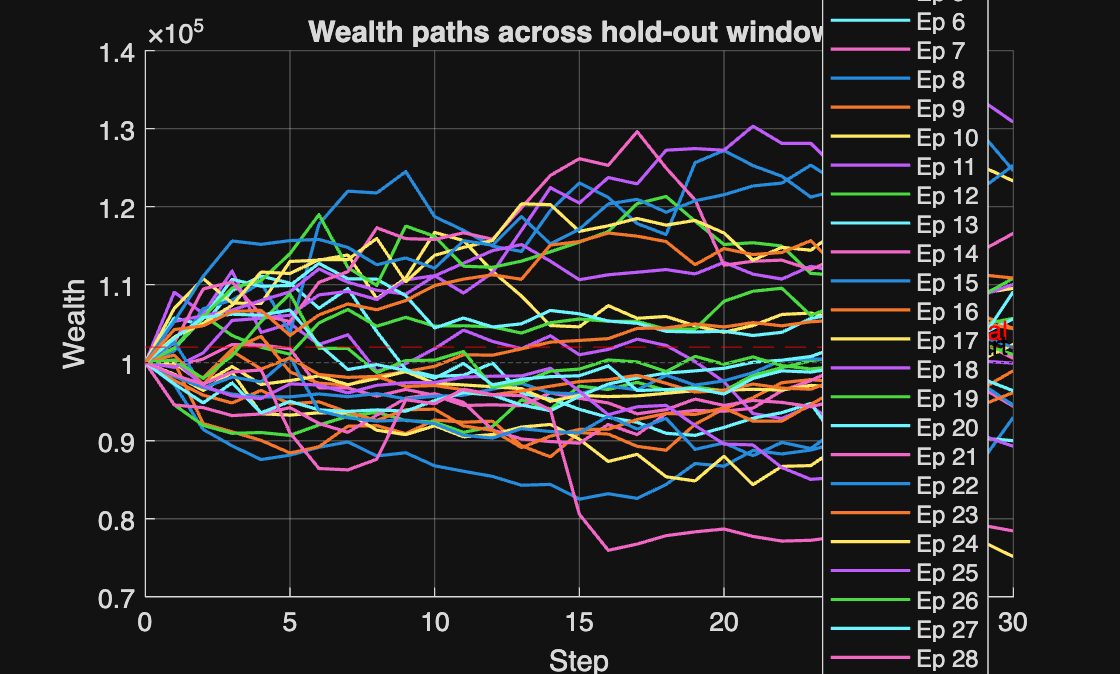

figure('Name','Hold-out wealth paths');
hold on;
for ep = 1:numEvalEpisodes
    if ~isempty(allWealthPaths{ep})
        plot(0:horizonPeriods, allWealthPaths{ep}, 'LineWidth', 1.2, ...
            'DisplayName', sprintf('Ep %d', ep));
    end
end
yline(goalWealth, '--r', 'Goal');
yline(initialWealth, ':k', 'Start');
xlabel('Step'); ylabel('Wealth');
title('Wealth paths across hold-out windows');
legend('Location','best'); grid on;

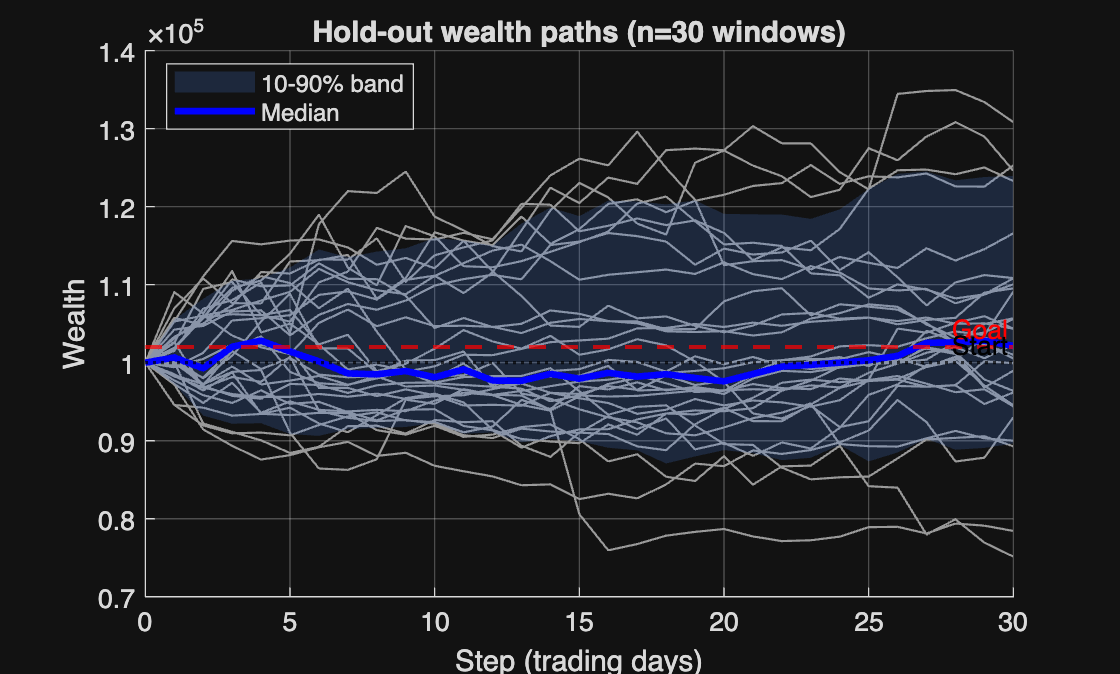

%% Plot wealth paths
figure('Name','Hold-out wealth paths');
hold on;

allW = nan(numEvalEpisodes, horizonPeriods+1);
for ep = 1:numEvalEpisodes
    if ~isempty(allWealthPaths{ep})
        allW(ep, :) = allWealthPaths{ep}';
    end
end

steps = 0:horizonPeriods;

for ep = 1:numEvalEpisodes
    plot(steps, allW(ep,:), 'Color', [0.6 0.6 0.6 0.3], 'LineWidth', 0.8, ...
        'HandleVisibility', 'off');
end

p10 = prctile(allW, 10, 1);
p90 = prctile(allW, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');

plot(steps, median(allW, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility','off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Hold-out wealth paths (n=%d windows)', numEvalEpisodes));
legend('Location','best');
grid on;

## Local Functions

function R = inputTestData(filename)
    pricesTT = readtable(filename, 'VariableNamingRule', 'preserve');
    P        = pricesTT{:, 2:end};
    R        = diff(log(P));
end